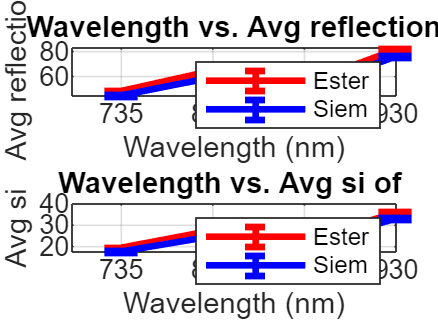

% Define arrays for marker sizes, marker types, and line widths
    %markerSizes = [4, 6, 8, 10]; % Different sizes for each point
    %arkerTypes = {'s', 'o', 'o', 'd'}; % Circle, Square, Triangle, Diamond
    lineWidths = [1, 1.5, 2, 2.5]; % Different line widths for each plot
    lineColors = {'red', 'red', 'blue', 'red'}; % Colors for each plot
    lineStyles = {'-', '--', ':', '-.'}; % Solid, Dashed, Dotted, Dash-Dot
    wavelengths = [735, 800, 865, 930]; 
    name = {'Ester', 'Siem'};

    % Initialize a figure 
    figure;
    
    % Define the filename prefixes
    prefixes = {'Avg reflection', 'Avg si'};
    
    for j = 1:2:4
        data = load(sprintf('%s %d.mat', prefixes{1}, j));      
        subplot(2,1,1)   
        errorbar(wavelengths, data.avg_refl,data.rf_std_error,...
                'LineWidth', lineWidths(3), ...
                'Color', lineColors{j}, ...
                'LineStyle', lineStyles{1}, ...
                'CapSize', 10); % Add cap size for visibility
         % Set labels and title for the first subplot
        hold on;
         data_siem = load(sprintf('%s %d.mat', prefixes{2}, j));      
        % Create the second subplot for the last two plots
        subplot(2, 1, 2); % Second subplot for the last two plots
        errorbar(wavelengths, data_siem.avg_si_refl,data_siem.si_std_error, ...
                'LineWidth', lineWidths(3), ...
                'Color', lineColors{j}, ...
                'LineStyle', lineStyles{1}, ...
                'CapSize', 10); % Add cap size for visibility
            hold on; % Keep the current plot for the next iteration
       
    end
    subplot(2,1,1)
    xlabel('Wavelength (nm)');
    ylabel(prefixes{1});
        set(gca, 'XTick', wavelengths); % Set x-tick positions to the wavelengths
        set(gca, 'XTickLabel', string(wavelengths)); % Optionally set x-tick labels
        grid on;
        title(sprintf('Wavelength vs. %s', prefixes{1})); % Dynamic title
        
    legend('Ester', 'Siem');
    subplot(2,1,2)
     % Set labels and title for the second subplot
        xlabel('Wavelength (nm)');
        ylabel(prefixes{2});
        set(gca, 'XTick', wavelengths); % Set x-tick positions to the wavelengths
        set(gca, 'XTickLabel', string(wavelengths)); % Optionally set x-tick labels
        grid on;
        title(sprintf('Wavelength vs. %s of %s', prefixes{2}));
    legend('Ester', 'Siem');

    saveas(gcf, "average_siem_ester.png");
    
    hold off; % Release the plot

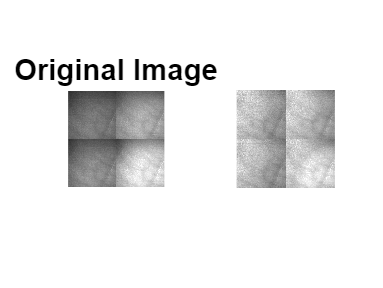

i = im2double(imread("Image_000001.png"));     % Read the image
w = im2double(imread("w.png"));     % Read the image
d = im2double(imread("b.png"));
img=(i-d)./(w-d);
imshow(img)